# Odometry affected by noise

From an ideal point of view, The Odometry would calculate exact pose of the robot over time. Unfortunately due to factors such, wind,  slipery  ground ,tire size among many physical factors , is impossible. Therefore the odometry works correctly in short intervals. To know the pose of the robot over time more effectively, probabilistic methods such as the Extended Kalaman Filter (which will be studied later) can be used. The image below shows  how the odometry differs from robot pose  over time.

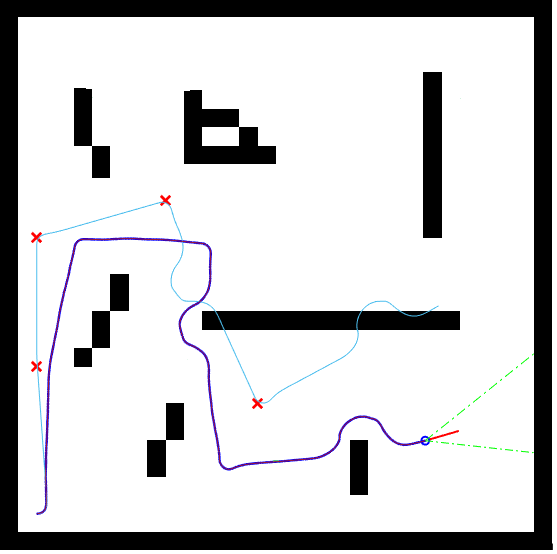

As We mention before, in practice is common to indicate linear and angular velocities instead of wheel velocities, for that in future lessons We will use robot velocities.

In simulation is easy to  get robot pose over time however you must have a source of noise to practice in a mor realistic scenario. For that We will show you how to add noise to simulations.

Define a visualizer and set up  a diferential robot (as you learn in previous lessons).

viz = Visualizer2D;
initPose = [ 0; 0; 0]; % [x ; y ; theta]    

R = 0.1; 
L = 0.5; 
mobileRobot = DifferentialDrive(R,L);
viz.robotRadius = .3;

sampleTime = .1;          % Sample time [s]
tVec = 0:sampleTime:5;     % Time array  in this example te execution will run for 3 seconds
r = rateControl(1/sampleTime);

Define an array of poses where  We  will store each pose computed by odometry.

odom_pose = zeros(3,numel(tVec));

odom_pose(:,1) = initPose;
currentPose = initPose;



Before start simulation set a variance for each velocity, We will add gaussian noise with 0 mean.

varianceV= 0.1; %.3 
varianceW= 0.13; % .1

for idx = 2:numel(tVec) 

Define  a constant linear velocity and a variable  angular velocity. With  inverseKinematics function get $\omega_R$ and $\omega_L$ for calculate odometry.

    
    v = 0.3;
    w = pi*(cos(idx/2));
    [wL,wR] = inverseKinematics(mobileRobot,v ,w);

Add noise to  velocities to compute final pose.

    
    noiseV = v  + normrnd(0,varianceV);
    noiseW = w + normrnd(0,varianceW);
    bodyV = [noiseV ;0;noiseW];    % Body velocities [vx;vy;w]  vy = 0 because the differential robot can not move in y axis.
        
    

            Compute  odometry 

    d_sr = R * wR * sampleTime;
    d_sl = R * wL * sampleTime;
    d_s = (d_sr + d_sl)/2;
    d_theta = (d_sr - d_sl)/L;
    
    % Store each pose computed by odometry
    odom_pose(:,idx) = odom_pose(:,idx-1) + [ d_s *cos(odom_pose(3,idx-1) +  d_theta/2 ) ; 
                                              d_s *sin(odom_pose(3,idx-1) +  d_theta/2 );
                                              d_theta];             
    
    % Convert from robot body to world
    vel =  bodyToWorld(bodyV,currentPose);  
   
    % Perform forward discrete integration step
    currentPose = currentPose + vel * sampleTime; 
      
    % Update visualization
    viz(currentPose);

    %Wait for visualization rate
    waitfor(r);
end


Finally  plot odometry in the same visualizer.

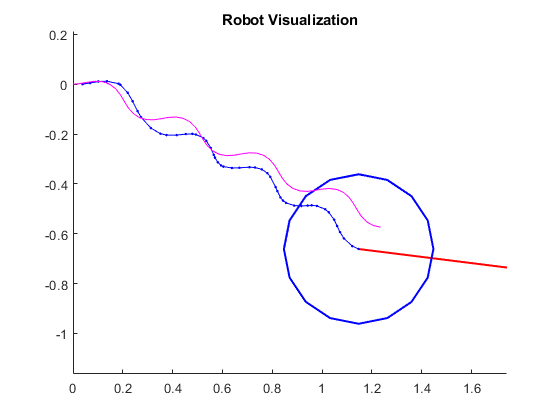

hold on
plot(odom_pose(1,:),odom_pose(2,:),'m');

As you can see, the odometry (pink line) is compute from velocities without noise (because in real world We does not know the added noise in heach movement). Blue line shows "real movements" with added noise.

# Practice

### Change trajectory by modify velocities also change variances and plot the results over the time. Analize the resulting graph ¿How much noise is acceptable in a short period of time?